% RESET;
clearvars -EXCEPT pollutionData_daily pollutionData_hourly % to be faster while debugging
clc; close('all'); fclose('all');
% clear; close('all'); fclose('all'); % NO clear screen

% Delete Previous pdf files
% folder = 'Figures'; %delete(strcat(folder ,'\*.pdf')); clear folder

## SET THE PATH -------------------------------------------------------------------

%restoredefaultpath 
%clear RESTOREDEFAULTPATH_EXECUTED;
pwd

ans = 'D:\Dropbox\00_PORTFOLIO_UC3M\00_PUBLICACIONES\00_Revistas\Drafts\2017_NPL_Special_Issue_IWANN2017\Paz\SourceCode\02_Arima_Paz'

## PAHT & FOLDERS ----------------------------------------------------------------

note: mfilename('fullpath')   does not work, up to now (2017 nov -Matlab 2017b)  in Live scripts

% folderFunctions  = '\Functions';
% folderTimeSeries = '\TimeSeries';
% folderFigures    = '\Figures';

%cd(fileparts(mfilename('fullpath')))    % does not work if executed by Run Section [and advance]
%folderFunctions  = strcat( fileparts(mfilename('fullpath')),'\Functions');
%folderTimeSeries = strcat( fileparts(mfilename('fullpath')),'\TimeSeries');
%folderFigures    = strcat( fileparts(mfilename('fullpath')),'\Figures');

folderFunctions  = strcat( pwd,'\Functions');
folderTimeSeries = strcat( pwd,'\TimeSeries');
folderFigures    = strcat( pwd,'\Figures');

oldpath = path; path(folderFunctions,oldpath)
oldpath = path; path(folderTimeSeries,oldpath)
oldpath = path; path(folderFigures,oldpath)
clear oldpath;
% --------------------------------------------------------------------------------

## COMPUTATION STEPS ------------------------------------------------------------------

computationSteps = [1 1];   
        % first value for analysis: TS,ACF, PACF, [ SCATTER PLOTS ]
        % second values to set/fit and forecast the ARIMA MODEL

## LOAD DATA EXAMPLE Type 1 (Examples from economics Tool box) =============

1.- DATA: Examples from economics Tool box

% % -----------------------------------------------
% tsFilename = 'Data_Airline.mat'; 
% tsName     = tsFilename( 6:(numel(tsFilename) - 4 ) ); % Airline
% load(fullfile(matlabroot,'examples','econ',tsFilename));
% Constant = 1; D = 1; Seasonality = 12; MALags = 12; SMALags = 12;
% setARIMAOpt = 2;

% -----------------------------------------------
% tsFilename = 'Data_Accidental.mat';   
% tsName     = tsFilename( 6:(numel(tsFilename) - 4 ) ); % Airline
% load(fullfile(matlabroot,'examples','econ',tsFilename));
% Constant = 1; D = 1; Seasonality = 12; MALags = 12; SMALags = 12;
% setARIMAOpt = 2;

% % -----------------------------------------------
% tsFilename = 'Data_PowerConsumption';   
% tsName     = tsFilename( 6:(numel(tsFilename) - 4 ) );
% load(fullfile(matlabroot,'examples','econ',tsFilename));
% % Constant = 1; D = 0; Seasonality = 1; MALags = 3; SMALags = 0;
% p = 1; D = 2; q = 0;
% setARIMAOpt = 1;
% Data = Data(:,2); % Data = Data(:,3); Data = Data(:,4);

% % -----------------------------------------------
% tsFilename = 'Data_Overshort';   
% tsName     = tsFilename( 6:(numel(tsFilename) - 4 ) );
% load(fullfile(matlabroot,'examples','econ',tsFilename));
% % Constant = 1; D = 1; Seasonality = 12; MALags = 24; SMALags = 24;
% p = 4; D = 0; q = 3;
% setARIMAOpt = 1;

## LOAD DATA EXAMPLE Type 2 (DATA FROM MADRID POLLUTION DATA)  ============

2.- DATA: load DATA FROM MADRID POLLUTION DATA

% % LOAD WHOLE DATA and seve it in a cell array --- 
%  
% tsInfoCellArray = {"NO2" , "NO2" ,"NO2" ,"NO2" ,...
%                    "PM25" ,"PM25" ,"O3" ,"O3" ,};                
% 
% filenameTS = {'ts-PC-08-SC-47-H-pproc.dat' , ... 
%               'ts-PC-08-SC-50-H-pproc.dat' , ...
%               'ts-PC-08-SC-56-H-pproc.dat' , ...
%               'ts-PC-08-SC-59-H-pproc.dat' , ...
%               'ts-PC-09-SC-47-H-pproc.dat' , ...
%               'ts-PC-09-SC-50-H-pproc.dat' , ...
%               'ts-PC-14-SC-56-H-pproc.dat' , ...
%               'ts-PC-14-SC-59-H-pproc.dat' };          
% 
% % NO2FdzLadreda          
% % tsFilename = 'ts_PC_08_SC_56_H_pproc.dat'; 
% tsFilename = filenameTS{3}; 
% tsName     = tsFilename( 4:(numel(tsFilename) - 12 ) );        
% Data       = load( strcat( folderTimeSeries, '\', tsFilename) );
% Constant = 1; D = 1; Seasonality = 12; MALags = 12; SMALags = 12;
% setARIMAOpt = 2;

## LOAD DATA EXAMPLE Type 3 (DATA FROM MADRID POLLUTION DATA)  ==========

3.- DATA: LOAD DATA FROM MADRID POLLUTION DATA: 2016 - 11 -----------------------------------------------------

tsInfoCellArray = {"NO2" , "NO2" ,"O3","PM25" };                

filenameTS = {'ts-NO2-FedzLadreda-16-12.csv' , ... 
              'ts-NO2-PzCastilla-16-10.csv' , ...
              'ts-O3-JuanCarlosI-16-07.csv' , ...
              'ts-PM25-MendezAlvaro-16-10.csv'};

for i =1:numel(filenameTS)
    nChar = numel(filenameTS{i});
    strName = filenameTS{i};
    tsNames{i} = strName(4:(nChar-4));
end
              
% tsNames =  {'NO2-FedzLadreda-16-12', ... 
%             'NO2-PzCastilla-16-10' , ...
%             'O3-JuanCarlosI-16-07' , ...
%             'PM25-MendezAlvaro-16-10'};          
% nY = 16; nM = 11; % data not needed    

%---------------------------------------------------------

% tsInfoCellArray = {"NO2" , "NO2" ,"NO2" ,"NO2" ,...
%                    "PM25" ,"PM25" ,"O3" ,"O3" ,};                
% 
% filenameTS = {'ts-PC-08-SC-47-16-08.dat' , ... 
%               'ts-PC-08-SC-50-16-08.dat' , ...
%               'ts-PC-08-SC-56-16-08.dat' , ...
%               'ts-PC-08-SC-59-16-08.dat' , ...
%               'ts-PC-09-SC-47-16-08.dat' , ...
%               'ts-PC-09-SC-50-16-08.dat' , ...
%               'ts-PC-14-SC-56-16-08.dat' , ...
%               'ts-PC-14-SC-59-16-08.dat' };
% 
% nY = 16; nM = 08; % data not needed

## (ANALYSIS AND MODEL OF EACH OF THE TIME SERIES) ===========================================

============================================================================================

`      ANALYSIS AND MODEL OF EACH OF THE TIME SERIES`

============================================================================================ ============================================================================================

showScatterLag    = 0;
showTrainTest     = 0;
showTsTRansformed = 0;
showTsAcfPacf     = 0;
showModelResidual = 1;
showModelForecast = 1;


%for indexTs = 1:numel(filenameTS)
for indexTs = 1:1
%for indexTs = 2:2
%for indexTs = 3:3
%for indexTs = 4:4
        
    close('all'); fclose('all');
        
    % NO2FdzLadreda  % tsFilename = 'ts_PC_08_SC_56_H_pproc.dat'; 
    tsFilename = filenameTS{indexTs}; 
    
    tsName     = tsNames{indexTs};   % tsName     = tsFilename( 4:(numel(tsFilename) - 4 ) ); 
    Data       = load( strcat( folderTimeSeries, '\', tsFilename) );
    
    %  Set the model to be estimated 
    switch tsName
        case 'NO2-FedzLadreda-16-12'
            Constant = 1; D = 1; 
            Seasonality = 24; MALags = 24; SMALags = 24;
            setARIMAOpt = 2; 
            
            %p = 24; D = 1; q = 24;
            %setARIMAOpt = 1;
        
        case 'NO2-PzCastilla-16-10'
            Constant = 1; D = 1; 
            Seasonality = 24; MALags = 24; SMALags = 24;
            setARIMAOpt = 2; 
            
            p = 24; D = 1; q = 24;
            setARIMAOpt = 1;
        
        case 'O3-JuanCarlosI-16-07'
            Constant = 1; D = 1; Seasonality = 24; MALags = 24; SMALags = 24;
            setARIMAOpt = 2; 
            
            p = 24; D = 1; q = 24;
            setARIMAOpt = 1;
        
        case 'PM25-MendezAlvaro-16-10'
            Constant = 1; D = 0; Seasonality = 24; MALags = 24; SMALags = 24;
            setARIMAOpt = 2; 
            
            p = 24; D = 1; q = 24;
            setARIMAOpt = 1;
    end

## SET DATA for the script and define TRAIN, TEST, VALIDATION

-----------------------------------------------------------------------

    ts_Data01  = Data;  clear Data;
    nTs        = numel(ts_Data01);

    prctTrain = 0.9;
    prctValid = 0.0;                         % ARIMA (i.e. Box-Jenkins has no validation subset) REVIEW THIS 
    prctTest  = 1 - prctValid - prctTrain;   % This prctg must the same than 

    numLags    = 75;       % 3 days

## PROCESS the time series Data but only to show figures= ======================

============================================================================= Process: logarithm ; diff( (1-L)y_t ); (1-L)y_t) - (1-L)Ly_t = 1 -2Ly_t + L^2_y_t L y(t) = y(t-1)

    preProcessTSData = 1;

    if preProcessTSData 
        ts_Data01_Log = log(ts_Data01);
        nTsLog = numel(ts_Data01_Log);

        ts_Data01_Dif = ts_Data01(2:nTs) - ts_Data01(1:(nTs-1));
        nTsDif = numel(ts_Data01_Dif);

        ts_Data01_Dif2 = ts_Data01_Dif(2:nTsDif) - ts_Data01_Dif(1:(nTsDif-1));
        nTsDif2 = numel(ts_Data01_Dif2);

        ts_Data01_LogDif = ts_Data01_Log(2:nTsLog) - ts_Data01_Log(1:(nTsLog-1));
        nTsLogDif = numel(ts_Data01_LogDif);

        % Log of a difference is a bad idea, because we should log a negative values ...
        % ts_Data01_DifLog = log(ts_Data01_Dif);
        % nTsDifLog = numel(ts_Data01_DifLog);

        % Show the time series and its processing -------------------------------------------------------------
        if ( showTsTRansformed ) 
            h0a = figure('Name',tsFilename( 1:numel(tsFilename) ) );
            subplot(3,2,1); plot(ts_Data01,        '-s','MarkerSize',3); title(tsName);
            subplot(3,2,2); plot(ts_Data01_Log,    '-s','MarkerSize',3); title('TS log');
            subplot(3,2,3); plot(ts_Data01_Dif,    '-s','MarkerSize',3); title('TS (1-L)y_t');
            subplot(3,2,4); plot(ts_Data01_LogDif, '-s','MarkerSize',3); title('TS ( (1-L)Log(y_t) )');
            subplot(3,2,5); plot(ts_Data01_Dif2,   '-s','MarkerSize',3); title('TS ( (1-L)y_t) - (1-L)Ly_t ) )');

            % Log of a difference is a bad idea, because we should log a negative values ...
            subplot(3,2,6); plot(0,0, '-s','MarkerSize',3); title('TS ( Log( (1-L)y_t) ) -> bad idea');

            filename = strcat(tsName,'_transformed');
            format = '-dpdf'; folder = folderFigures;
            [ error ] = saveFigure( h0a , format, folder , filename );
        end
        
    end

    if preProcessTSData
        showScatterPlot  = 1;
        showACFPACFPlot  = 0;

        if ( showScatterLag ) 
            %sInfo <- type of Pollutant (for the limit ofthe axes in the figures) 
            sInfo = tsInfoCellArray{indexTs}; % sInfo = ''; 
            [ACF, lagsACF, boundsACF, PACF, lagsPACF , boundsPACF , ... 
             hScatter, hAcf, hPacf] = getLagScatterPlot_ACF_PACF_v01( ts_Data01 , tsName, sInfo, numLags, showScatterPlot, showACFPACFPlot );

            filename = strcat(tsName,'_scatter_Lag');
            format = '-dpdf'; folder = folderFigures;
            [ error ] = saveFigure( hScatter , format, folder , filename );
        end
    end

    % ------------------------------------------------------
    % Show the TS and the ACF y PACF of TS Data
    
    if showTsAcfPacf 
        h0b = figure('Name',tsFilename( 1:numel(tsFilename) ) );
        subplot(2,2,1:2); plot(ts_Data01,'-s','MarkerSize',3); title( tsName );
        subplot(2,2,3);   autocorr(ts_Data01,numLags);         title( 'ACF');
        subplot(2,2,4);   parcorr(ts_Data01,numLags);          title( 'PACF');
        
        filename = strcat(tsName,'_TS+ACF+PACF');
        format = '-dpdf'; folder = folderFigures;
        [ error ] = saveFigure( h0b , format, folder , filename );
    end

## GET A MODEL, EVALUATE THE MODEL , FORECAST with the model ============================

========================================================================================

    if (computationSteps(2) == 0)
        continue
    end

    fprintf('--------------\ntsName %s\n',tsName);

--------------
tsName NO2-FedzLadreda-16-12


    % ======================================================================

## Step 01 - Specify the model

    %{
    filenameTS = {'ts-NO2-FedzLadreda-16-12.csv' , ... 
                  'ts-NO2-PzCastilla-16-10.csv' , ...
                  'ts-O3-JuanCarlosI-16-07.csv' , ...
                  'ts-PM25-MendezAlvaro-16-10.csv'};

    %}
    % p = 6; D = 1; q = 6; % P = 26; D = 2; q = 26;
    % toEstMd1 = arima(p,D,q);
    % Constant = 1; D = 1; Seasonality = 12; MALags = 24; SMALags = 24;
     if ( setARIMAOpt == 1)
        toEstMd1 = arima(p,D,q);
     elseif ( setARIMAOpt == 2) 
        toEstMd1 = arima('Constant',Constant,'D',D,'Seasonality',Seasonality, 'MALags',MALags,'SMALags',SMALags);
     end

    % +++++++++++++++++++++++++++++++++++++++++++
    % Seed
    v = (int32(clock)); seed = v(6); clear v; rng(seed);  % seed is the second for time 
    fprintf('Seed: %03d\n',seed);

Seed: 035



    % ======================================================================

## Step 02 - Estimate the Model Using Presample Data.

    pSt            = 13;   % num initial values of the observations to be taken as initial values
    pSt = max(toEstMd1.P,toEstMd1.Q);
    %pSt = min(toEstMd1.P,toEstMd1.Q);

    preSampleTimes = 1:pSt;
    y0 = ts_Data01(preSampleTimes);

    nTsTrain = fix(nTs * prctTrain) ;

    trainTimes = ( ( preSampleTimes( end ) + 1):nTsTrain );
    testTimes  = ( ( trainTimes( end ) + 1 ):( nTs ));

    nTs_Valid = 0;
    nTs_Test = numel(testTimes );

    ts_Data01_Presample = ts_Data01( preSampleTimes) ; 
    ts_Data01_Train = ts_Data01( trainTimes) ; 
    ts_Data01_Test  = ts_Data01( testTimes ) ;

    %{
    % SHOW Y0 values - TRAIN TEST
    h1a = figure('Name',tsFilename( 1:numel(tsFilename) ) );
    plot( preSampleTimes , y0              , '-sk','MarkerSize',3); hold on ;
    plot( trainTimes     , ts_Data01_Train , '-sb','MarkerSize',3); hold on;
    plot( testTimes      , ts_Data01_Test  , '-sr','MarkerSize',3); 
    title(tsName);
    % savingg pdf 
   
    filename = strcat(tsName,'_train-test');
    format = '-dpdf'; folder = folderFigures;
    [ error ] = saveFigure( h1a , format, folder , filename );
    %}
    
    % residualsTrain_0 = infer(toEstMd1,ts_Data01_Train,'Y0',y0);
    % h1a_2 = figure('Name',strcat( tsFilename( 1:end), 'train target(b) output(g)'  ) );
    % plot( preSampleTimes , y0              , '-sk','MarkerSize',3); hold on ;
    % plot( trainTimes   , ts_Data01_Train , '-sb','MarkerSize',3); hold on;
    % plot( trainTimes   , ts_Data01_Train + residualsTrain, '-sr','MarkerSize',3); hold on;
    % title(strcat(tsName,' residuals toEstMdl '));
    % % savingg pdf 

    [EstMd1,EstParamCov, logL, info] = estimate( toEstMd1 , ts_Data01_Train, 'Y0' , y0,...
                                                 'Display','off'); % Class: arima

    % ======================================================================
    % Step 03 -  Infer the residuals from the fitted model. 

    residualsTrain = infer(EstMd1,ts_Data01_Train,'Y0',y0);
    numObs = numel(ts_Data01_Train);

    [trainRMSE, trainSMAPE] = getTsErrors_v1 (ts_Data01_Train, (ts_Data01_Train + residualsTrain), numObs); 

    fprintf('\nTrain residuals results - times %d\n%12s %12s\n%12.5f %12.5f\n\n',...
             numObs,'rmse', 'smape',trainRMSE, trainSMAPE);


Train residuals results - times 621
        rmse        smape
     0.85369     20.52954



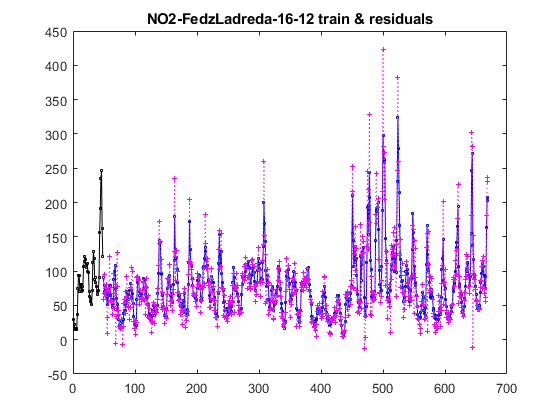


    
    % SHOW TRAIN RESIDUALS 
    if (showModelResidual)              
        h1b = figure('Name',strcat( tsFilename( 1:end), 'train target(b) output(g)'  ) );
        plot( preSampleTimes , y0              , '-sk','MarkerSize',3); hold on ;
        plot( trainTimes   , ts_Data01_Train , '-sb','MarkerSize',3); hold on;
        plot( trainTimes   , ts_Data01_Train + residualsTrain, ':+m','MarkerSize',3); hold on;
        title(strcat( tsName, ' train & residuals'));
        % Saving pdf ------------- 
        filename = strcat(tsName,'_trainResiduals');
        format = '-dpdf'; folder = folderFigures;
        [ error ] = saveFigure( h1b , format, folder , filename );
    end

    % [ ts_Data_01_Train_Ouptut , E ] = simulate(EstMd1,numObs,'Y0',y0, 'NumPaths', 100); 
    % h1c = figure('Name',strcat( tsFilename( 1:end), 'train target(b) output(g)'  ) );
    % plot( trainTimes   , ts_Data_01_Train_Ouptut  , '-sg','MarkerSize',3); 
    
             

    % ======================================================================
    % Step 04 - Forecast 
     
    % From the periods to be forecasted, i.e. horizon h, then 
    periods = length(ts_Data01_Test); 
    pStF = max(EstMd1.P,EstMd1.Q);
    preSampleTimes = trainTimes((end - pStF):end);
    Y04F = ts_Data01_Train((end - pStF):end);

    [ ts_Data01_Forecasted , ts_Data01MSE , V ] = forecast(EstMd1,periods, 'Y0',Y04F);

    % ------------------------------------------
    [forecastRMSE , forecastSMAPE ] = getTsErrors_v1 (ts_Data01_Test,ts_Data01_Forecasted, periods); 
    fprintf('\nforecasted times %d\n%12s %12s\n%12.5f %12.5f\n\n',...
             periods,'rmse', 'smape',forecastRMSE, forecastSMAPE);


forecasted times 75
        rmse        smape
    28.70359    112.04092



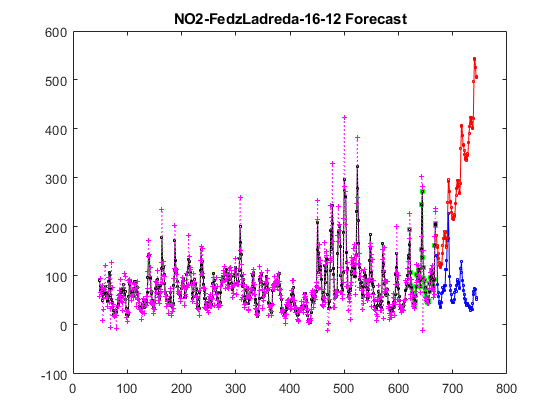


    % -------------------------------------------
    if (showModelForecast)
        a = trainTimes(end) + 1; b = trainTimes(end)+periods; 
        forecastedTimes = ( a:b); clear a b;


        h1d = figure('Name',strcat( tsFilename( 1:end), '  train target(b) forecast (g)'  ) );
        plot( preSampleTimes    , Y04F                 , '-sg','MarkerSize',5); hold on ;
        plot( trainTimes        , ts_Data01_Train      , '-sk','MarkerSize',3); hold on;
        plot( trainTimes        , ts_Data01_Train + residualsTrain, ':+m','MarkerSize',3); hold on;
        plot( testTimes         , ts_Data01_Test       , '-sb','MarkerSize',3); hold on;
        plot( forecastedTimes   , ts_Data01_Forecasted , '-sr','MarkerSize',3); hold on;
        title(strcat( tsName, ' Forecast'));

        % Saving pdf ------------- 
        filename = strcat(tsName,'_forecast');
        format = '-dpdf'; folder = folderFigures;
        [ error ] = saveFigure( h1d , format, folder , filename );

    end

    fprintf('\nEnd of this section - %s\n', tsName);


End of this section - NO2-FedzLadreda-16-12


    % return;
    
end